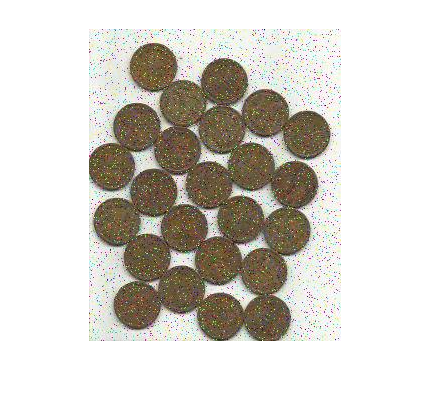

% Useful functions: imhist, graythresh, imbinarize, im2bw, imcomplement,
% strel, imerode, imdilate, imopen, imclose, imfill, label2rgb.

% Need to read in a greyscale image as it'll be 2D and not 3D.
coins = imread('corrupted_coins.jpg'); % Step 1
holes = imread('holes_corrupted_coins.png');

orig = coins;

figure
imshow(coins);

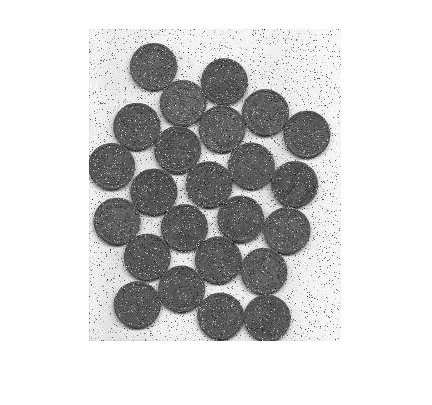

coins = rgb2gray(coins);

figure
imshow(coins);

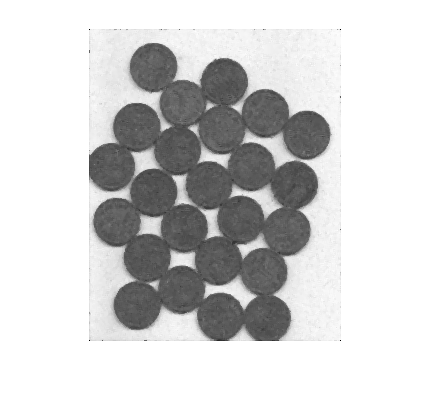

coins = medfilt2(coins);

figure
imshow(coins);

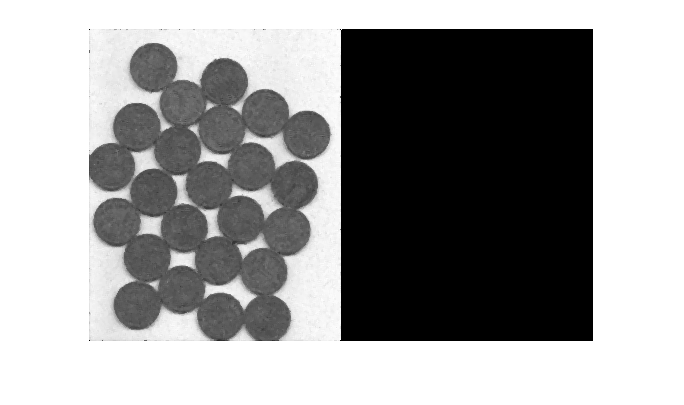


% coins_manthresh = coins>50;
% imshowpair(coins,coins_manthresh,'montage');
% imshow(coins_manthresh);

coins_manthresh = graythresh(coins);
imshowpair(coins,coins_manthresh,'montage');

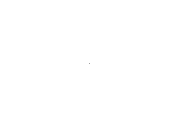

imshow(coins_manthresh);

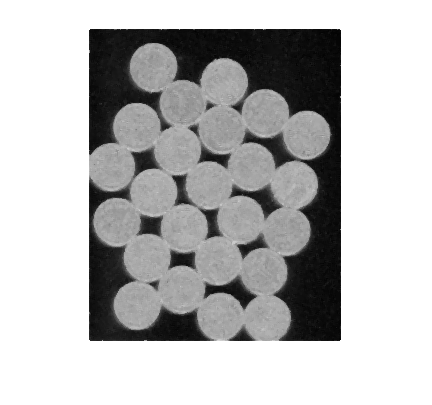


coins = imcomplement(coins);
figure
imshow(coins);

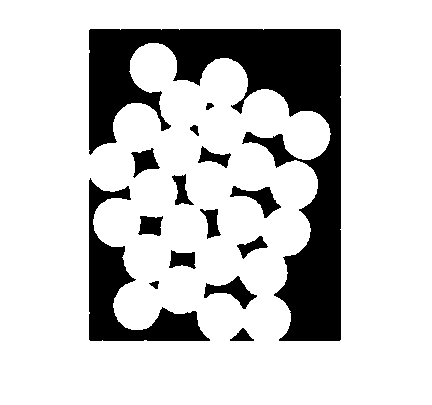


% coins_filled = imfill(coins, 'holes');
% 
% imshow(coins_filled);

bw_coins = imbinarize(coins);
imshow(bw_coins);

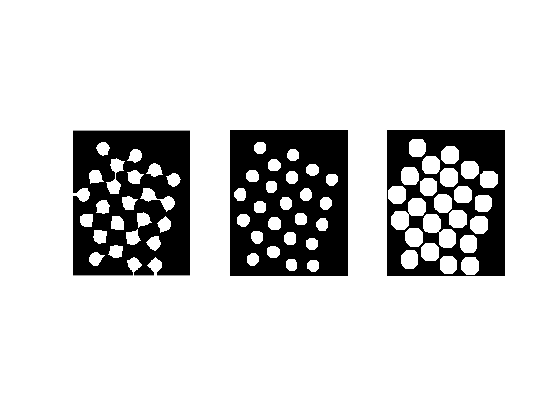


se = strel('disk',10,4);
open_se = strel('disk',12,4);
dilate_se = strel('disk',7,4);
erodeBW = imerode(bw_coins,se);
openBW = imopen(erodeBW,open_se);
dilateBW = imdilate(openBW,dilate_se);
figure
subplot(1,3,1);
imshow(erodeBW);
subplot(1,3,2);
imshow(openBW);
subplot(1,3,3);
imshow(dilateBW);

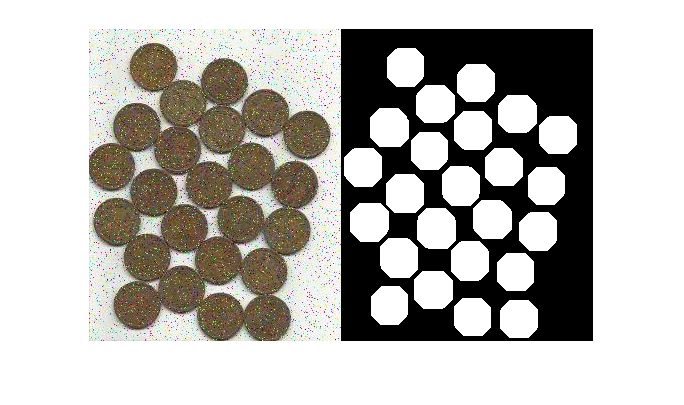


figure
imshowpair(orig,dilateBW,'montage');

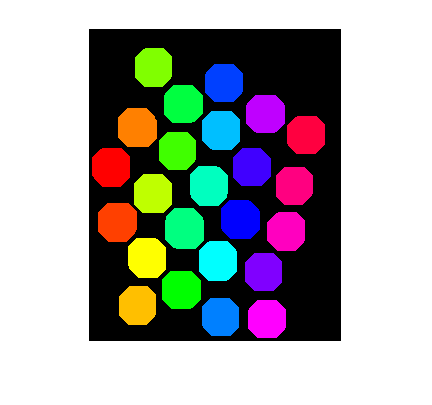


bw = dilateBW;
% cc = bwconncomp(bw);
% l = labelmatrix(cc);
[l, connected] = bwlabel(bw,4);

rgb = label2rgb(l,'hsv','k');

connected = string(connected);

figure
imshow(rgb);


blobMeasurements = regionprops(rgb,orig,'all');

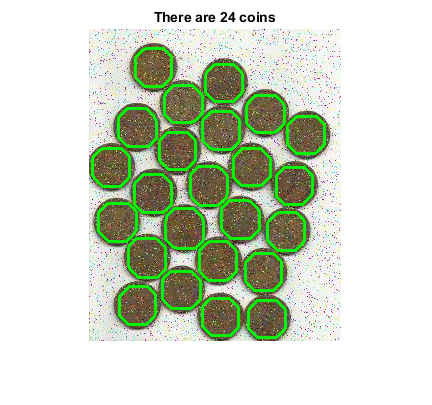

numberOfBlobs = size(blobMeasurements, 1);

figure
subplot(1,1,1);
imshow(orig);
titlestr = append("There are ", connected, " coins");
title(titlestr);
axis image;
hold on;
bounds = bwboundaries(bw);
numberOfBounds = size(bounds,1);
for k = 1 : numberOfBounds
	thisBoundary = bounds{k};
	plot(thisBoundary(:,2), thisBoundary(:,1), 'g', 'LineWidth', 2);
end
hold off;


% coins2 = coins>100;
% 
% coins3 = imfill(coins2,'holes');
% 
% [L, n]=bwlabel(coins3);
% disp(n);
% 
% blobs = regionprops(L, 'BoundingBox');
% blobs(1).BoundingBox;





% bw_in = im2bw(coins); % Step 2
% bw_in = imfill(bw_in,'holes'); % Step 3
% bw_out = bw_in; % Step 4
% 
% prop = regionprops(bw_in, {'Area', 'Centroid'}); % Step 5 (get properties)
% 
% prop = struct2table(prop); % Step 6 (return properties in a table)
% 
% thr = coins>100;
% imshow(thr);
% 
% grey_coins = rgb2gray(coins);
% grey_holes = rgb2gray(holes);
% 
% % Need to convert greyscale image into a 1D binary image that'll be a mask
% 
% coin_lvl = graythresh(coins);
% disp(coin_lvl);
% hole_lvl = graythresh(holes);
% 
% bw_coins = imbinarize(coins,coin_lvl);
% 
% 
% % Need to fill any holes in the regions of the binary image
% bw_coins = imfill(bw_coins, 'holes');
% 
% comp = imcomplement(bw_coins);
% 
% figure
% imshowpair(coins,comp,'montage');
% 
% figure
% imshowpair(coins,bw_coins,'montage');
% title('graythresh');
% 
% cross = [0 1 0; 1 1 1; 0 1 0];
% box = [1 1 1; 1 1 1; 1 1 1];
% 
% se = strel('disk',3,6);





